% F-16 lateral regulator
% JSH 3/9/20
clear all global;

% Plant dynamics
A =[-0.322 0.0640 0.0364 -0.9917 0.0003 0.0008 0;       % x1 = beta
    0 0 1 0.0037 0 0 0;                                 % x2 = phi
    -30.6492 0 -3.6784 0.6646 -0.7333 0.1315 0;         % x3 = p
    8.5396 0 -0.0254 -0.4764 -0.0319 -0.0620 0;         % x4 = r
    0 0 0 0 -20.2 0 0;                                  % x5 = delta_a
    0 0 0 0 0 -20.2 0;                                  % x6 = delta_r
    0 0 0 57.2958 0 0 -1];                              % x7 = x_w

B = [0 0; 
    0 0; 
    0 0; 
    0 0; 
    20.2 0; 
    0 20.2; 
    0 0];          % u1 = delta_a (aileron)
                   % u2 = delta_r (rudder)
C = [0 0 0 57.2958 0 0 -1;                              % y1 = r_w (washed out yaw rate)
    0 0 57.2958 0 0 0 0;                                % y2 = p
    57.2958 0 0 0 0 0 0;                                % y3 = beta
    0 57.2958 0 0 0 0 0];                               % y4 = phi
   
D = zeros(4,2);

% Static feedback controller u = -Ky
K = [-0.56 -0.44 -0.11 -0.35; 
    -1.19 -0.21 -0.44 0.26];

G = minreal(ss(A, B, C, D));
L = G * K;
So = (eye(4) + L)^-1;
To = L * So;

s = tf('s');
A = 4;
M = 10;
wb = 3;
tau = 0.02;
r0 = 0.05;
rinf = 0.4;
Wo = eye(4) * ((tau * s) + r0) / ((tau * s / rinf) + 1);
Wp = eye(4) * ((s/M) + wb) / (s + (wb*A));

% Nominal Performance
Nominal_Performance = norm(Wp * To, 'inf')

Nominal_Performance = 0.8292


%  Robust Stability
Robust_Stability = norm(Wo * So, 'inf')

Robust_Stability = 0.5076

u0 = 0.4 * 1126;
Yr = 0;
Nr = -0.639;
Nbeta = 15.16;
Ybeta = -110.94;
Ndela = 0.334;
Ydelr = 19.65;
Ndelr = -6.732;

A = [(Ybeta/u0) -(1-(Yr/u0)); Nbeta Nr];
B = [0 Ydelr/u0; Ndela Ndelr];
C = eye(2);
D = 0;

G = ss(A,B,C,D);

M = 2;
A = 0.005;
wb = 1;
Wp = eye(2) * ((s/M)+wb) / (s+(wb*A));

systemnames = 'G Wp';
inputvar = '[w(2); u(2)]';
outputvar = '[Wp; -G-w]';
input_to_G = '[u]';
input_to_Wp = '[G+w]';
sysoutname = 'P';
sysic;

[K,CL,GAM,info] = hinfsyn(minreal(ss(P)), 2, 2, 'method', 'ric', 'Tolgam', 1e-3, 'DISPLAY', 'on');


  Test bounds:  0.5 <=  gamma  <=  0.5043

    gamma        X>=0        Y>=0       rho(XY)<1    p/f
  5.022e-01     5.9e-10     0.0e+00     9.519e-16     p
  5.011e-01     5.9e-10     0.0e+00     1.749e-17     p
  5.005e-01     5.9e-10     0.0e+00     1.760e-15     p
  5.003e-01     5.9e-10     0.0e+00     3.179e-16     p
  Limiting gains...
  5.005e-01    -1.0e+00 #  -2.1e-16     1.427e-20     f

  Best performance (actual): 0.5001


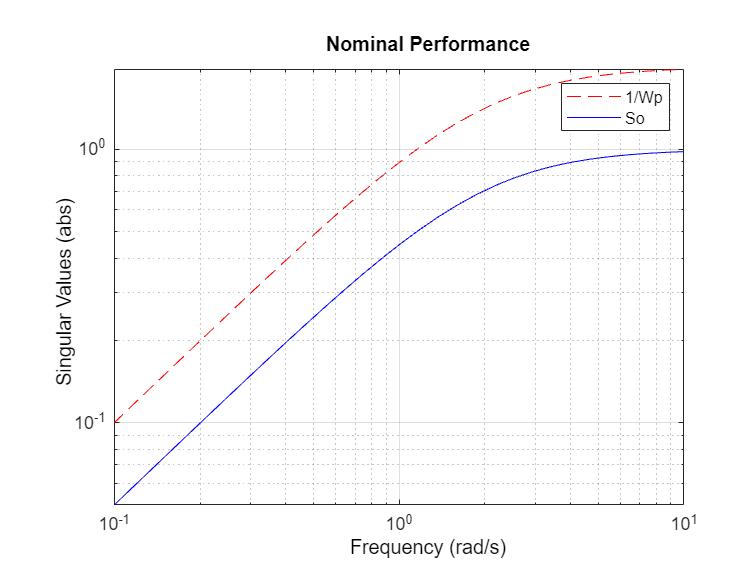

L = minreal(G * K);
So = (eye(2)+L)^-1;
To = L * So;

figure
hold on
h = sigmaplot(inv(Wp), 'r--', So, 'b-');
setoptions(h,'MagUnits','abs', 'XLim', [1e-1,1e1]);
legend("1/Wp", "So")
title("Nominal Performance")

u0 = 0.4 * 1126;
Yr = 0;
Nr = -0.639;
Nbeta = 15.16;
Ybeta = ureal('Ybeta',-110.94, 'Percentage', 20);
Ndela = 0.334;
Ydelr = 19.65;
Ndelr = -6.732;

A = [(Ybeta/u0) -(1-(Yr/u0)); Nbeta Nr];
B = [0 Ydelr/u0; Ndela Ndelr];
C = eye(2);
D = 0;

G = ss(A,B,C,D);

M = 2;
A = 0.005;
wb = 1;
Wp = eye(2) * ((s/M)+wb) / (s+(wb*A));

systemnames = 'G Wp';
inputvar = '[w(2); u(2)]';
outputvar = '[Wp; -G-w]';
input_to_G = '[u]';
input_to_Wp = '[G+w]';
sysoutname = 'P';
sysic;

[K,CL,GAM,info] = hinfsyn(minreal(ss(P)), 2, 2, 'method', 'ric', 'Tolgam', 1e-3, 'DISPLAY', 'on');


  Test bounds:  0.5 <=  gamma  <=  0.5043

    gamma        X>=0        Y>=0       rho(XY)<1    p/f
  5.022e-01     5.9e-10     0.0e+00     9.519e-16     p
  5.011e-01     5.9e-10     0.0e+00     1.749e-17     p
  5.005e-01     5.9e-10     0.0e+00     1.760e-15     p
  5.003e-01     5.9e-10     0.0e+00     3.179e-16     p
  Limiting gains...
  5.005e-01    -1.0e+00 #  -2.1e-16     1.427e-20     f

  Best performance (actual): 0.5001


L = minreal(G * K);
So = (eye(2)+L)^-1;
To = L * So;

CL_sys = lft(P, K);
[N, Delta, BlkStruct] = lftdata(CL_sys);
szDelta = size(Delta);
N11 = N(1:szDelta(2),1:szDelta(1));
freq = logspace(-1,1);
N11_frd = frd(N11,freq);
[mubnds] = mussv(N11_frd,BlkStruct);

Points completed: 50/50


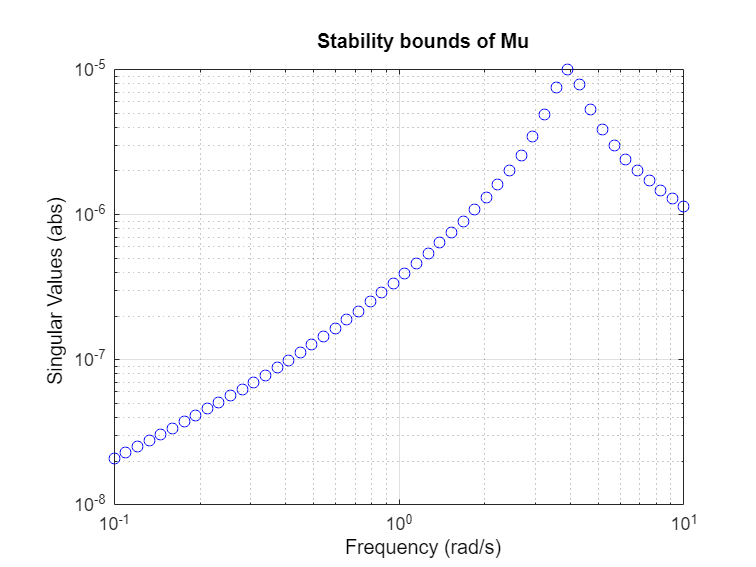


% plot Stability Bounds
figure; clf;
sigmaplot(mubnds(1,1), 'bo', mubnds(1,2), 'r-');
setoptions(h,'MagUnits','abs', 'XLim', [1e-1,1e1]);
title("Stability bounds of Mu")

% 
N_frd = frd(N,freq);
clear BlkStruct; BlkStruct = [-1 0; 2 2];
[mu_N] = mussv(N_frd,BlkStruct);

Points completed: 50/50


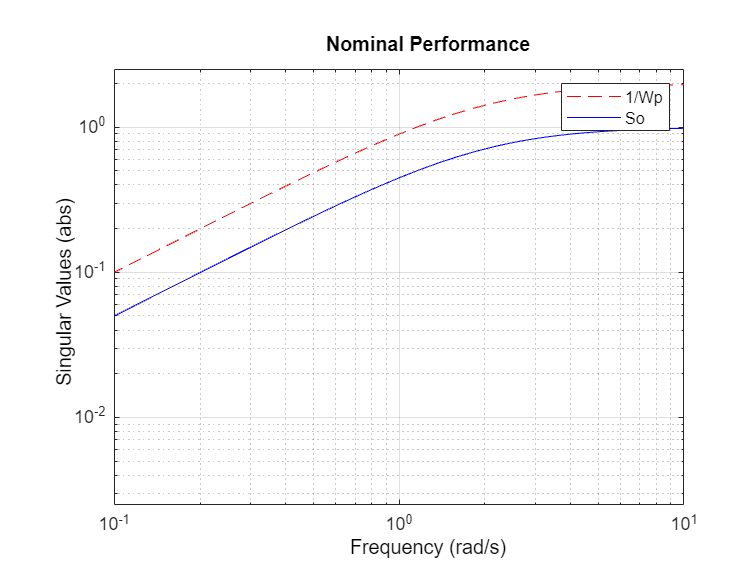


% plot Performance
figure; clf;
sigmaplot(mu_N(1,1), 'bo', mu_N(1,2), 'r-');
setoptions(h,'MagUnits','abs', 'XLim', [1e-1,1e1]);

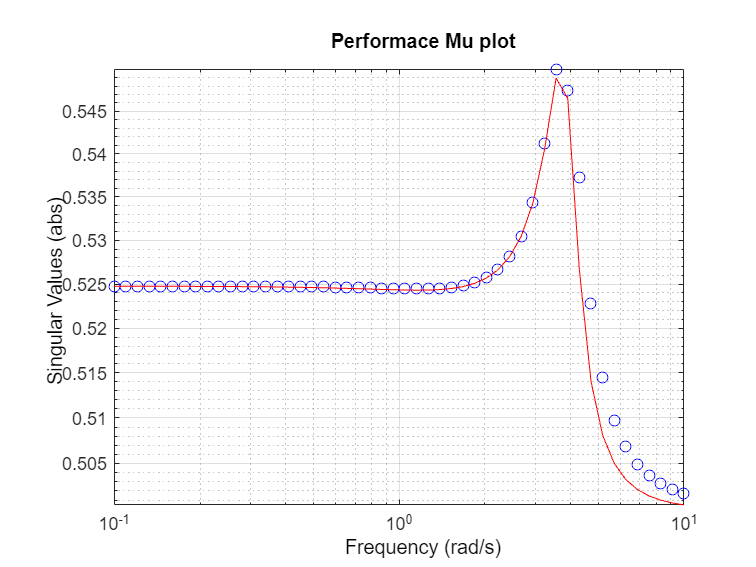

title("Performace Mu plot")

u0 = 0.4 * 1126;
Yr = 0;
Nr = -0.639;
Nbeta = ureal('Nbeta', 15.16, 'percentage', 30);
Ybeta = ureal('Ybeta',-110.94, 'Percentage', 20);
Ndela = 0.334;
Ydelr = 19.65;
Ndelr = -6.732;

A = [(Ybeta/u0) -(1-(Yr/u0)); Nbeta Nr];
B = [0 Ydelr/u0; Ndela Ndelr];
C = eye(2);
D = 0;

G = ss(A,B,C,D);

M = 2;
A = 0.005;
wb = 1;
Wp = eye(2) * ((s/M)+wb) / (s+(wb*A));

systemnames = 'G Wp';
inputvar = '[w(2); u(2)]';
outputvar = '[Wp; -G-w]';
input_to_G = '[u]';
input_to_Wp = '[G+w]';
sysoutname = 'P';
sysic;

[K,CL,GAM,info] = hinfsyn(minreal(ss(P)), 2, 2, 'method', 'ric', 'Tolgam', 1e-3, 'DISPLAY', 'on');


  Test bounds:  0.5 <=  gamma  <=  0.5043

    gamma        X>=0        Y>=0       rho(XY)<1    p/f
  5.022e-01     5.9e-10     0.0e+00     9.519e-16     p
  5.011e-01     5.9e-10     0.0e+00     1.749e-17     p
  5.005e-01     5.9e-10     0.0e+00     1.760e-15     p
  5.003e-01     5.9e-10     0.0e+00     3.179e-16     p
  Limiting gains...
  5.005e-01    -1.0e+00 #  -2.1e-16     1.427e-20     f

  Best performance (actual): 0.5001


L = minreal(G * K);
So = (eye(2)+L)^-1;
To = L * So;

CL_sys = lft(P, K);
[N, Delta, BlkStruct] = lftdata(CL_sys);
szDelta = size(Delta);
N11 = N(1:szDelta(2),1:szDelta(1));
freq = logspace(-1,1);
N11_frd = frd(N11,freq);
[mubnds] = mussv(N11_frd,BlkStruct);

Points completed: 50/50


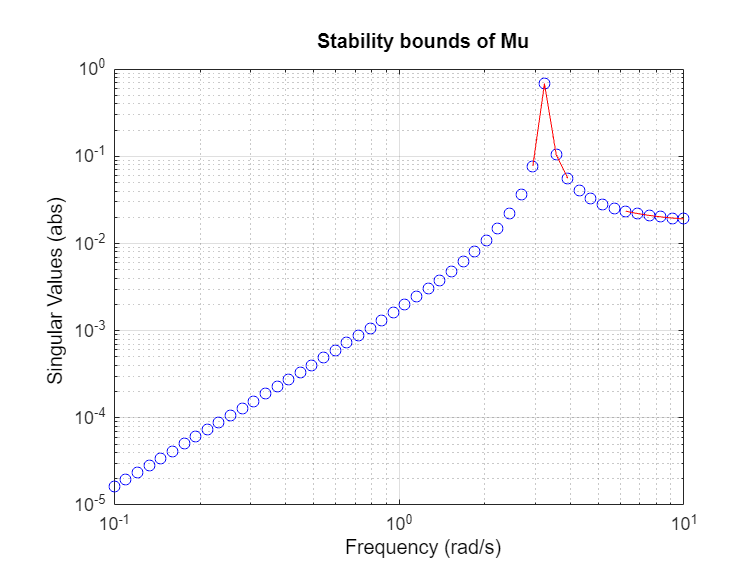


% plot Stability Bounds
figure; clf;
h = sigmaplot(mubnds(1,1), 'bo', mubnds(1,2), 'r-');
setoptions(h,'MagUnits','abs', 'XLim', [1e-1,1e1]);
title("Stability bounds of Mu")

% 
N_frd = frd(N,freq);
clear BlkStruct; BlkStruct = [-1 0; -1 0; 2 2];
[mu_N] = mussv(N_frd,BlkStruct);

Points completed: 50/50


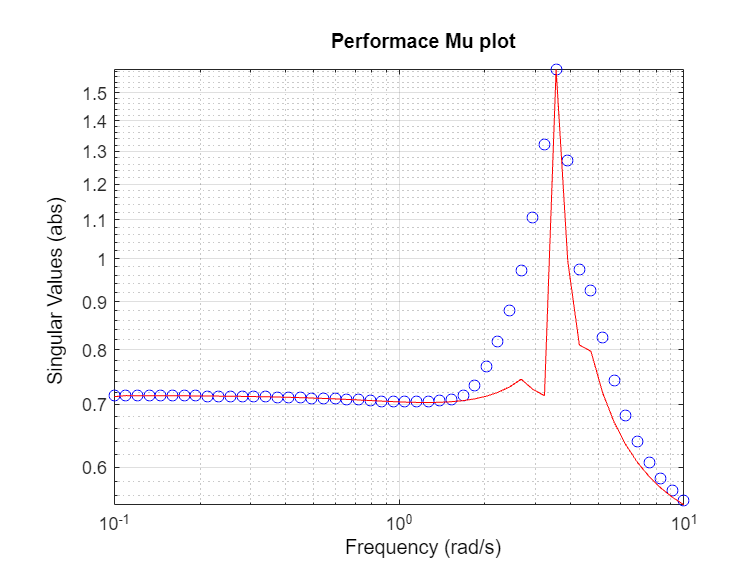


% plot Performance
figure; clf;
h = sigmaplot(mu_N(1,1), 'bo', mu_N(1,2), 'r-');
setoptions(h,'MagUnits','abs', 'XLim', [1e-1,1e1]);
title("Performace Mu plot")